Let's start by fixing the path


clear
clc

full_path='D:\MATLAB AP Package Beta\';
project_path='D:\MATLAB AP Package Beta\Scratch\Week 3\';

addpath(genpath([full_path,'Data\']));
addpath(genpath([full_path,'Functions\']));
addpath(genpath(project_path));
cd(project_path);

clear full_path project_path  


## Let's start with long-run reversals (DeBondt and Thaler, 1985).

We'll replicate Table VI in Fama and French (1996), since that's the result that really sold the Fama and French (1993) three-factor model. 

clear
clc

load NYSE
load ret
load me
load dates
load ff

Next, we need to create the long-run reversal variables. The cookbook already creates these in makeCRSPDerivedVariables(), but it's easy enough to do that here too:

% Leave only NYSE stocks 
sortRet = ret;
sortRet(NYSE ~= 1) = nan;

% Create the sorting variables in a structure 
ppStruct(1).R = makePastPerformance(sortRet, 12, 1); 
ppStruct(1).label = {'12-2'};

ppStruct(2).R = makePastPerformance(sortRet, 24, 1); 
ppStruct(2).label = {'24-2'};

ppStruct(3).R = makePastPerformance(sortRet, 36, 1); 
ppStruct(3).label = {'36-2'};

ppStruct(4).R = makePastPerformance(sortRet, 48, 1); 
ppStruct(4).label = {'48-2'};

ppStruct(5).R = makePastPerformance(sortRet, 60, 1); 
ppStruct(5).label = {'60-2'};

ppStruct(6).R = makePastPerformance(sortRet, 60, 12);
ppStruct(6).label = {'60-13'};

Now let's run the sorts:

nPPVars = length(ppStruct);
for i = 1:nPPVars
    % Sort first
    ind = makeUnivSortInd(ppStruct(i).R, 10);
    
    
    % Run a bivariate sort (we'll need the GRS test for Table VII) for th
    % late sample first. For Table VI, you can run a univariate sort too
    [res, ~] =  runBivSort(ret, ind, 5, 2, dates, me, 'weighting', 'e', ...
                                                      'factorModel', 3, ...
                                                      'timePeriod', [193012 196306], ...
                                                      'printResults', 0, ...
                                                      'plotFigure', 0);
    resEarly(i,1) = res;
    
    % Late sample
    [res, ~] =  runBivSort(ret, ind, 5, 2, dates, me, 'weighting', 'e', ...
                                                      'factorModel', 3, ...
                                                      'timePeriod', [196306 199312], ...
                                                      'printResults', 0, ...
                                                      'plotFigure', 0);
    resLate(i,1) = res;
end

Print the results:

outputTable = [[resLate.xret] ...
               [resEarly.xret]]';
info.rnames = char([{''}; [ppStruct.label]'])
info.width = 160;

fprintf('Late sample results (07/1963 - 12/1993):\n');
mprint(outputTable(1:nPPVars, :), info);

fprintf('Early sample results (01/1931 - 06/1963):\n');
mprint(outputTable(nPPVars+1:end, :),info);

Compare with FF96 Table VI:

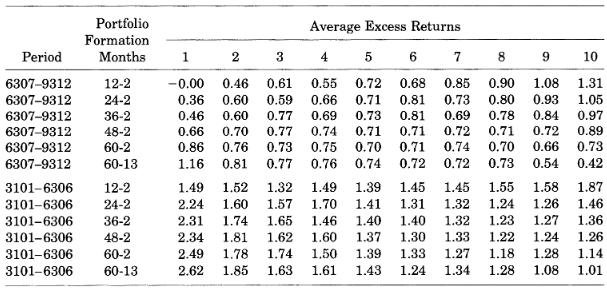

Now let's do Table 7. The results structure above should have all the results we need. Print the first panel first (t-12 to t-2):

clc

% Choose the first results structure (t-12 to t-2)
r = strcmp([ppStruct.label], {'12-2'});
res = resLate(r);

% Get the output table 
outputTable = [ res.alpha'; ...
               [res.factorLoadings.b]'; ...
                res.talpha'; ...
               [res.factorLoadings.t]'; ...
                res.r2'];

% Store the row names
info.rnames = char([{'','a','b','s','h','t(a)','t(b)','t(s)','t(h)','R^2'}]);
info.width = 160;

% Print
fprintf('Portfolio formation months are t-12 to t-2\n');
mprint(outputTable, info);
fprintf('GRS statistic is %2.4f, and its b-value is %2.4f.\n', res.grsFstat(1), res.grsPval(1));

Compare with:

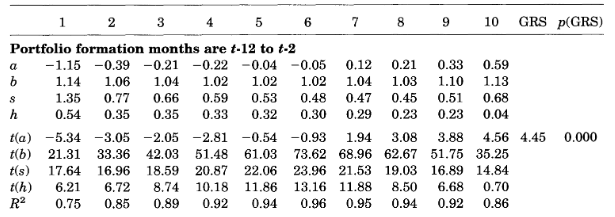

Now do the second panel (t-48 to t-2):

clc

% Choose the fourth results structure (t-48 to t-2)
r = strcmp([ppStruct.label], {'48-2'});
res = resLate(r);

% Get the output table 
outputTable = [ res.alpha'; ...
               [res.factorLoadings.b]'; ...
                res.talpha'; ...
               [res.factorLoadings.t]'; ...
                res.r2'];

% Store the row names
info.rnames = char([{'','a','b','s','h','t(a)','t(b)','t(s)','t(h)','R^2'}]);
info.width = 160;

% Print
fprintf('Portfolio formation months are t-12 to t-2\n');
mprint(outputTable, info);
fprintf('GRS statistic is %2.4f, and its b-value is %2.4f.\n', res.grsFstat(1), res.grsPval(1));

Compare with:

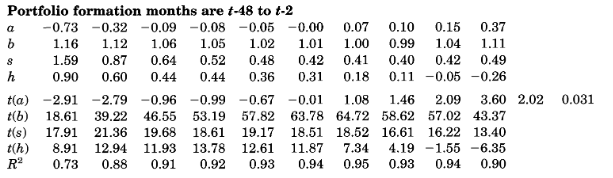

And finally the third, last panel:

clc

% Choose the last results structure (t-60 to t-13)
r = strcmp([ppStruct.label], {'60-13'});
res = resLate(r);

% Get the output table 
outputTable = [ res.alpha'; ...
               [res.factorLoadings.b]'; ...
                res.talpha'; ...
               [res.factorLoadings.t]'; ...
                res.r2'];

% Store the row names
info.rnames = char([{'','a','b','s','h','t(a)','t(b)','t(s)','t(h)','R^2'}]);
info.width = 160;

% Print
fprintf('Portfolio formation months are t-60 to t-13\n');
mprint(outputTable, info);
fprintf('GRS statistic is %2.4f, and its b-value is %2.4f.\n', res.grsFstat(1), res.grsPval(1));

Compare with: 

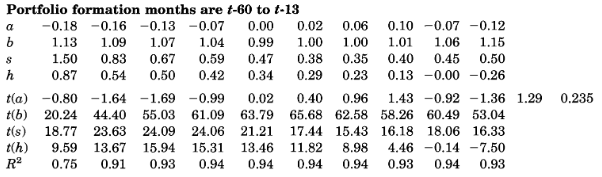

A much easier way to see that long-run reversals are explain by the three-factor model is just to do a spanning test:

clear
clc

load ret
load nyse
load dates
load me
load bm

% Pick the sorting specifications
nPtf = 5;
weighting = 'e';
timePeriod = 196306;

R6013 = makePastPerformance(ret, 60, 12);
indR6013 = makeUnivSortInd(-R6013, nPtf, NYSE);
resR6013 = runUnivSort(ret, indR6013, dates, me, 'weighting', weighting, ...
                                                 'timePeriod', timePeriod);

indBM = makeUnivSortInd(bm, nPtf, NYSE);
resBM = runUnivSort(ret, indBM, dates, me, 'weighting', weighting, ...
                                           'timePeriod', timePeriod);

indMe = makeUnivSortInd(-me, nPtf, NYSE);
resMe = runUnivSort(ret, indMe, dates, me, 'weighting', weighting, ...
                                           'timePeriod', timePeriod);


retR6013 = resR6013.pret(:, end);
retBM = resBM.pret(:, end);
retMe = resMe.pret(:, end);
const = 0.01*ones(size(retR6013));

prt(nanols(retR6013,[const]))
prt(nanols(retR6013,[const retBM retMe]))

or run a FamaMacBeth regression:

runFamaMacBeth(100*ret, -R6013, dates, 'timePeriod', timePeriod);
runFamaMacBeth(100*ret, [-R6013 log(me) log(bm)], dates, 'timePeriod', timePeriod);

## Let's look at momentum now

Start with the classic momentum result:

clear
clc

load ret
load dates
load me
load nyse
load ff

nPtf = 5;
timePeriod = 196306;

R122 = makePastPerformance(ret, 12, 1);
indR122 = makeUnivSortInd(R122, 10, NYSE);
resR122 = runUnivSort(ret, indR122, dates, me, 'weighting', 'v', ...
                                           'printResults', 0, ...
                                           'plotFigure', 0);


Now let's do that for the recent and intermediate past performance:

% intermediate
R127 = makePastPerformance(ret, 12, 6);
indR127 = makeUnivSortInd(R127, 10, NYSE);
resR127 = runUnivSort(ret, indR127, dates, me, 'weighting', 'v', ...
                                           'printResults', 0, ...
                                           'plotFigure', 0);

% Recent
R62 = makePastPerformance(ret, 6, 1);
indR62 = makeUnivSortInd(R62, 10, NYSE);
resR62 = runUnivSort(ret, indR62, dates, me, 'weighting', 'v', ...
                                           'printResults', 0, ...
                                           'plotFigure', 0);

Store the long/short return series and compare their performance:

ret122 = resR122.pret(:, end);
ret127 = resR127.pret(:, end);
ret62 = resR62.pret(:, end);

figure;
ibbots([ret122 ret127 ret62], dates, 'timePeriod', timePeriod, ...
                                     'legendLabels', {'12-2','12-7','16-2'});

Now let's replicate Novy-Marx (2012) Table 2. Determine the sample:

s = find(dates==192701);
e = find(dates==201012);
const(1:s-1) = nan;
const(e+1:end) = nan;

Next let's run the regressions corresponding to the columns in the table:

% These correspond to columns
res(1, 1) = nanols(ret127, const);
res(2, 1) = nanols(ret127, [const mkt]);
res(3, 1) = nanols(ret127, [const ff3(:, 2:end)]);
res(4, 1) = nanols(ret127, [const ff4(:, 2:end)]);
res(5, 1) = nanols(ret62, const);
res(6, 1) = nanols(ret62, [const mkt]);
res(7, 1) = nanols(ret62, [const ff3(:, 2:end)]);
res(8, 1) = nanols(ret62, [const ff4(:, 2:end)]);

Print the results:

coefs = nan(6, 8);
tstats = nan(6, 8);

for i = 1:length(res)
    for j = 1:length(res(i).beta)
        coefs(j, i) = res(i).beta(j);
        tstats(j, i) = res(i).tstat(j)
    end
    coefs(end, i) = res(i).rbar;
end

% mat2Tex(coefs, tstats, {'Intercept','MKT','SMB','HML','UMD','Adj. R^2'})
info.rnames = char({'','Intercept','MKT','SMB','HML','UMD','Adj. R^2'});
mprint(coefs, info);
mprint(tstats, info);

Compare with:

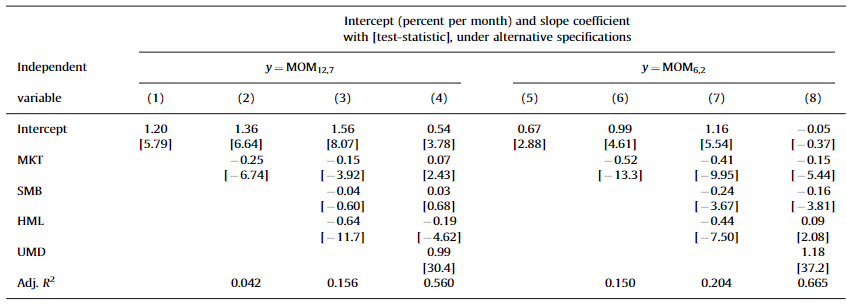

While we are at momentum, it's worth looking at its relationship with fundamental momentum, i.e., PEAD:

clear
clc

load ret
load nyse
load dates
load me
load CAR3 % Can use SUE here

% Pick the sorting specifications
nPtf = 10;
weighting = 'v';
timePeriod = 197306;

R122 = makePastPerformance(ret, 12, 1);
indR122 = makeUnivSortInd(R122, nPtf, NYSE);
resR122 = runUnivSort(ret, indR122, dates, me, 'weighting', weighting, ...
                                                 'timePeriod', timePeriod);

indCAR3 = makeUnivSortInd(CAR3, nPtf, NYSE);
resCAR3 = runUnivSort(ret, indCAR3, dates, me, 'weighting', weighting, ...
                                           'timePeriod', timePeriod);


retR122 = resR122.pret(:, end);
retCAR3 = resCAR3.pret(:, end);
const = 0.01*ones(size(retR122));

prt(nanols(retR122,[const]))
prt(nanols(retCAR3,[const]))

prt(nanols(retR122,[const retCAR3]))
prt(nanols(retCAR3,[const retR122]))

## Let's look at industry momentum next

The cookbook actually creates an industry return variable based on the FF49 industries. That is done in the makeCRSPDerivedVariables() function. The variable is called ireta and it assigned to every (month, permno) cell the return corresponding to FF49 industry the company is classified into that month. 

clear
clc

load ret
load ireta
load ff
load iret
load dates
load me
load nyse
load R
load SIC

nPtf = 10;

% This will make the 12-2 based on the industry returns 
iR122 = makePastPerformance(ireta, 12, 1);

% Let sort on the 12-2 industry return
indIR122 = makeUnivSortInd(iR122, nPtf, NYSE);
resIR122 = runUnivSort(ret, indIR122, dates, me);

% And on past month's industry return
indIR10 = makeUnivSortInd(ireta, nPtf, NYSE);
resIR10 = runUnivSort(ret, indIR10, dates, me);

% Store the long/short strategies
retIR122 = resIR122.pret(:, end);
retIR10 = resIR10.pret(:, end);

% Plot them
figure;
ibbots([retIR122 retIR10], dates, 'legendLabels',{'12-2','1-0'});

Let's see if it's a distinct effect from regular momentum using spanning tests:

R122 = makePastPerformance(ret, 12, 1);
indR122 = makeUnivSortInd(R122, nPtf, NYSE);
resR122 = runUnivSort(ret, indR122, dates, me, 'weighting', 'v', ...
                                               'printResults', 0, ...
                                               'plotFigure', 0);

retR122 = resR122.pret(:, end);
const = 0.01*ones(size(retR122));

prt(nanols(retIR10,[const]))
prt(nanols(retIR10,[const retR122]))

prt(nanols(retR122,[const]))
prt(nanols(retR122,[const retIR10]))

And here is a closer replication of Moskowtiz and Grinblatt (1999);


load SIC
SIC = floor(SIC/100);
SIC(isnan(SIC)) = 0;
indMG = 1  * (SIC>=10 & SIC<=14) + ...
        2  * (SIC==20) + ...
        3  * (SIC>=22 & SIC<=23) + ...
        4  * (SIC==26) + ...
        5  * (SIC==28) + ...
        6  * (SIC==29) + ...
        7  * (SIC==32) + ...
        8  * (SIC==33) + ...
        9  * (SIC==34) + ...
        10 * (SIC==35) + ...
        11 * (SIC==36) + ...
        12 * (SIC==37) + ...
        13 * (SIC>=38 & SIC<=39) + ...
        14 * (SIC==40) + ...
        15 * (SIC>=41 & SIC<=47) + ...
        16 * (SIC==49) + ...
        17 * (SIC==53) + ...
        18 * ((SIC>=50 & SIC<=52) | (SIC>=54 & SIC<=59)) + ...
        19 * (SIC>=60 & SIC<=69);

indMG(indMG==0 & SIC>0) = 20;

res = runUnivSort(ret, indMG, dates,me, 'weighting', 'v', ...
                                      'timePeriod', [196306 199507], ...
                                      'factorModel', 3, ...
                                      'addLongShort', 0, ...
                                      'printResults', 0, ...
                                      'plotFigure', 0);

nMonths = size(ret, 1);
nInds = 20;

s = find(dates==196306);
e = find(dates==199507);

iret = nan(nMonths, 20);
iret(s:e, :) = res.pret;

mcap = nan(nMonths, nInds);
mcap(s:e, :) = res.ptfMarketCap;

% Sort
ind = makeUnivSortInd(iret, 20);
ind = 1 * (ind>0 & ind<4) + ...
      2 * (ind>8 & ind<12) + ...
      3 * (ind>17);

res = runUnivSort(iret, ind, dates, mcap, 'weighting', 'e', ...
                                          'timePeriod', [196306 199507]);

Compare with their Table 3:

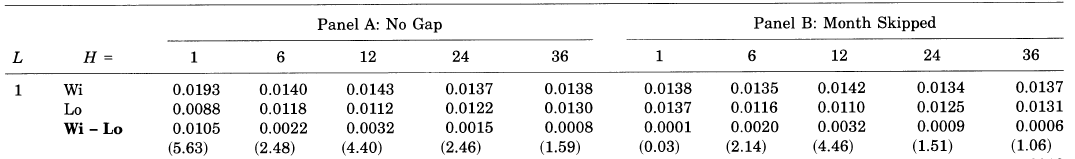

## Let's explore the government receivables 

Load the data first:

clear
clc

opts = detectImportOptions('us_company_receivables.csv');
data = readtable('us_company_receivables.csv', opts);

% Drop non-trading days
load ddates
ddates = datetime(ddates, 'ConvertFrom','yyyyMMdd');
indToDrop = ~ismember(data.date, ddates);
data(indToDrop, :) = [];

Let's load the CRSP_STOCKNAMES table too, since we'll use it for linking:

% Detect the import options
opts = detectImportOptions('crsp_stocknames.csv');

% Make sure ncusip is a character, as MATLAB sometimes reads it in as a
% numeric
indNcusip = strcmp(opts.VariableNames,'ncusip');
opts.VariableTypes(indNcusip) = {'char'};

% Read the crsp_stocknames csv
crsp_stocknames = readtable('crsp_stocknames.csv', opts);

We'll only use the end-of-month observations, so we'll sort the data and leave the last daily observation for each (company_bizportal_id, month) pair.

% Create the yyyymm date variable
data.yyyymm = year(data.date)*100 + month(data.date);

% Sort by id+date in ascending order
data=sortrows(data,{'company_bizportal_id','date'},'ascend');

% For each  (company_bizportal_id, yyyymm), leave the last observation. Use
% an anonymous function
fun = @(x) x(end,:); 
data = varfun(fun, data, 'GroupingVariables', {'company_bizportal_id','yyyymm'});

% Fix the variable names 
data.Properties.VariableNames = regexprep(data.Properties.VariableNames, 'Fun_', '');
data.GroupCount = [];

Note: in COMPUSTAT and in CRSP_STOCKANEMS, ncusip is the historical 8-digit CUSIP, while the cusip variable is the most recent one:

length(crsp_stocknames.ncusip{1})
crsp_stocknames(2:7, :) 

Let's create a cusip variable from the ISIN and we'll call it ncusip to match the name of the CRSP_STOCKANEMS variable that we'll use. 

data.ncusip = extractBetween(data.company_isin_number, 3, 10);

Now let's merge the data on both ticker and ncusip:

mergedData = outerjoin(data, crsp_stocknames, 'Type', 'Left', ...
                                               'LeftKeys', {'company_ticker_symbol', 'ncusip'}, ...
                                               'RightKeys', {'ticker', 'ncusip'}, ...
                                               'RightVariables', {'permno','ticker','ncusip','namedt','nameenddt','comnam'}, ...
                                               'MergeKeys', 1);


Since the links in crsp_stocknames are only valid for certain periods, we need to drop the observations in the merged dataset, for which the links are not relevant:

indToDrop = mergedData.date < mergedData.namedt | ...
            mergedData.date > mergedData.nameenddt | ...
            isnan(mergedData.permno);
mergedData(indToDrop,:) = [];

See if the names are a good match:

nameMatch = mergedData(:, {'company_ticker_symbol_ticker','yyyymm','company_name','comnam','permno'});

If it looks good, let's get to converting these to our familiar matrices. To do that, we need to ensure that we have unique (permno, yyyymm) rows. I'll only work with the "_all" forward- and backward-looking receivables, but you might want to include the rest of the variables too.

finalMergeData = mergedData(:,{'permno','yyyymm','fl_usd_value_all','bl_usd_value_all'});
finalMergeData = sortrows(finalMergeData, {'permno','yyyymm'}, 'ascend');
fun = @(x) x(end,:);
finalMergeData = varfun(fun, finalMergeData, 'GroupingVariables', {'permno','yyyymm'});
finalMergeData = sortrows(finalMergeData,'GroupCount','descend');
finalMergeData.Properties.VariableNames = regexprep(finalMergeData.Properties.VariableNames, 'Fun_', '');
finalMergeData.GroupCount = [];

There are some cases where the CRSP_STOCKNAMES links are messed up, some let's look into them:

rowInd = 1;
indLookInto = mergedData.permno == finalMergeData.permno(rowInd) & ...
              mergedData.yyyymm == finalMergeData.yyyymm(rowInd);
temp = mergedData(indLookInto, :);

And finally let's assign to our familiar matrices. We'll follow what the cookbook does for the COMPUSTAT variables. That is, we'll load the crsp_link table, we'll merge our new data to it, and we'll unstack it.

% This table is stored by the cookbook.
load crsp_link

% Merge the data
crsp_link = outerjoin(crsp_link, finalMergeData, 'Type', 'Left', ...
                                                 'LeftKeys', {'permno','dates'}, ...
                                                 'RightKeys', {'permno','yyyymm'}, ...
                                                 'MergeKeys',1);
% Unstack forward-looking receivables
fl_rec = unstack(crsp_link(:, {'permno','dates_yyyymm','fl_usd_value_all'}), 'fl_usd_value_all', 'dates_yyyymm');
fl_rec = table2array(fl_rec)';
fl_rec(1,:) = [];

% Unstack backward-looking receivables
bl_rec = unstack(crsp_link(:, {'permno','dates_yyyymm','bl_usd_value_all'}), 'bl_usd_value_all', 'dates_yyyymm');
bl_rec = table2array(bl_rec)';
bl_rec(1,:) = [];

% Store them 
save gov_rec fl_rec bl_rec

Now let's explore them. Start by loading a few variables:

clear
clc

load dates
load pdates
load me
load gov_rec 
load AT
load ATQ
load RECT
load RECTQ
load permno

Let's see how many observations we have relative to, say, market cap:

x = pdates;
y = [sum(isfinite(me), 2) sum(isfinite(bl_rec), 2) sum(isfinite(fl_rec), 2)];
plot(x, y);
legend('Market cap','Backward-looking receivables','Forward-looking receivables');
xlim([2012 2021]);

Let's look at the distributions for backward-looking receivables first:

x = pdates;
y = [prctile(bl_rec, [1 10 25 50 75 90], 2)];
plot(x, y);
xlim([2012 2021]);

And forward-looking receivables next:

x = pdates;
y = [prctiles(fl_rec, [1 10 25 50 75 90 99], 2)];
plot(x, y);
xlim([2012 2021]);

Boeing's permno is 19561. Let's look at what they've received 

load permno
cBA = find(permno == 19561);

x = pdates;
y = [bl_rec(:,cBA) fl_rec(:,cBA)];
plot(x, y);
legend('Backward-looking','Forward-looking')
xlim([2012 2021]);

Now let's scale receivables by the quarterly COMPSUTAT total receivables variable (RECTQ):

scldRec = (fl_rec/1e6)./RECTQ;

x = pdates;
y = [prctile(scldRec, [1 10 25 50], 2)];
plot(x, y);
xlim([2012 2021]);